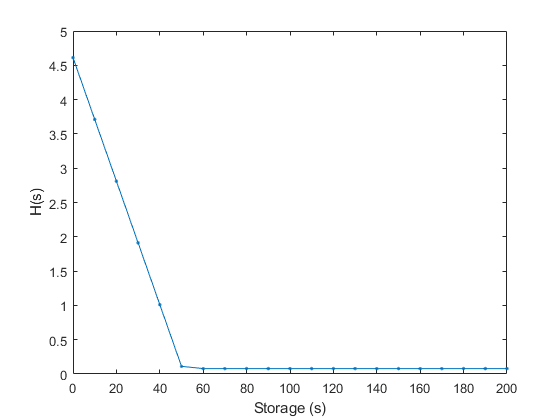

addpath("utils\")
discr_s = [0:10:200]' ;
discr_u = [0:10:200]' ;
discr_q = [0:10:80]' ;
discr_p = normpdf(discr_q,40,10);

% Irrigation extreme ( J = lambda*J_FLO + (1-lambda)*J_IRR )
lambda = .1 ;  
max_iter = 5; % max number of iteration for approximating the Bellman function
H = zeros( length(discr_s), 1) ;

for iter=1:max_iter
    Q = nan( length(discr_s), length(discr_u) );
    for i=1:length(discr_s)
        for j=1:length(discr_u)
%           Value function assignment
            Q(i,j) = value_function(H, lambda, discr_s(i), discr_u(j), discr_s, discr_q, discr_p);
        end
    end
    H = min(Q,[],2); % Min of each row
end

figure; plot(discr_s, H, '.-');
xlabel('Storage (s)'); ylabel('H(s)');

## SDP - Simulation based policy evaluation

data = load("data\Inflow_Test_AR0_1.txt");
n = data(1:150,2);
% plot(n)
h_init = 95; % Initial level
lamda = 0;
% % % Lake SDP simulation
[s, h, r] = simSDPLake(H, lamda, h_init, j, discr_u, discr_s, n, discr_q, discr_p);
% % % 
w = 50;
h_flo = 50;
g_flo1 = max(h(2:end) - h_flo, 0);
g_irr1 = max( w - r(2:end), 0);
J1 = [mean(g_flo1) mean(g_irr1)]

J1 =     2.0504   10.1636
